Checking the different modelling of the anticipation and pain stimulation. The multicolinearity might be an issue: 

-  [https://dartbrains.org/content/GLM_Single_Subject_Model.html#multicollinearity](https://dartbrains.org/content/GLM_Single_Subject_Model.html#multicollinearity)

- https://www.youtube.com/watch?v=U_rqhkaeB7Q

intermedpath='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles'; 
datapathorig='C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets'; %parent folder with the dataset files from the collection2015
datpathnew='C:\Users\lenov\Documents\PICO_DATA\';
load(fullfile(intermedpath,'data_frame'),'df');
%todo specify the columnids from the design matrix which are used in the
%calculation of the different contrasts.
painregressionidx={[1 2 3 7 8 9],... %{'atlas'             }
                   [2,5],... %{'bingel06'          }
                   [4 10 16 22],...   % {'bingel11'          }
                   [2 3 6 7],...%     {'eippert'           }
                   [3 4 17 18 31 32 45 46],...%     {'geuter'            },
                   [2 5],...%     {'kessner'           }
                   [28 34],...%     {'lui'               }
                   [4 9 14 19],...%     {'schenk'            }
                   [6 9],...%     {'theysohn'          }
                   [2 3 7 8 12 13 17 18],...%     {'wager04a_princeton'} 
                   [4 10],...%     {'wager04b_michigan' }
                   [4 6 12 14],...%     {'wrobel'            } the first two trial was modelled separately[3 5 11 13], as the contrast images are shared, i could check only the contrast in the SPM file and based on that it seems that the separately modelled first few trials were not used in the contrast which we use.
                   [1 9 17 25],...%     {'fehse'             }
                   [13 15 38 40],...%     {'hartmann'          }
                   [2 3 12 13],...%     {'meulen'            }
                   [20 22 28 30],...%     {'schenk17'          }
                   [10 14]%     {'schenk20'          }
                    
%     {'choi'              } done in FSL, in a separate part it is added
};

anticipationregressoridx={[14 15 16 20 21 22],... %atlas
                        [1 4],... %bingel2006
                        [3 9 15 21],... % {'bingel11'          }
                        [1 5],... %     {'eippert'           }
                        [1 15 29 43],...%     {'geuter'            },
                        [1 4],...%     {'kessner'           }
                        [16 22],...%     {'lui'               }
                        [3 8 13 18],...%     {'schenk'            }
                        [5 8],...%     {'theysohn'          }
                        [4 5 9 10 14 15 19 20],...%     {'wager04a_princeton'}
                        [2 8],...%     {'wager04b_michigan' } %this is the anticipation, but cue was also modelled as(1 7 betas)
                        [2 10],... %     {'wrobel'            } first few trials were modelled separaetly[1 9] see above detials
                        [2 10 18 26],...%     {'fehse'             }
                        [5 7 30 32],...%     {'hartmann'          }
                        [1 11],...%     {'meulen'            }
                        [19 27],...%     {'schenk17'          }
                        [9 13]%     {'schenk20'          }
                        
    
};

-------------------------------
-------------------------------
    "atlas"    "-0.046011"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Atlas_et_al_2012\remi1022s1\SPM.mat
-------------------------------
-------------------------------


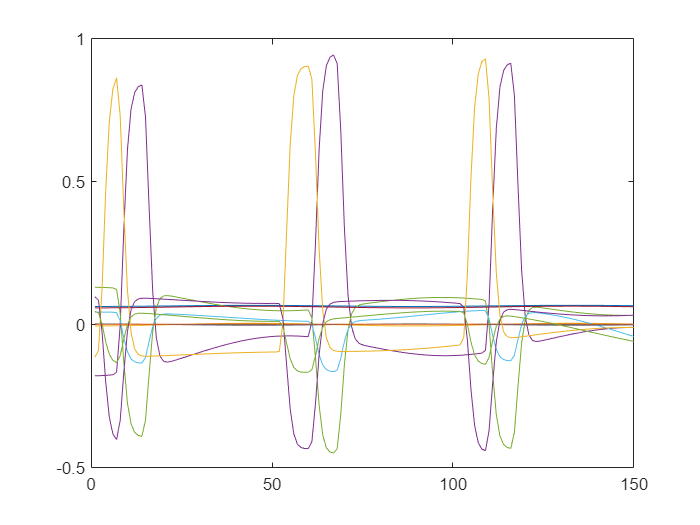

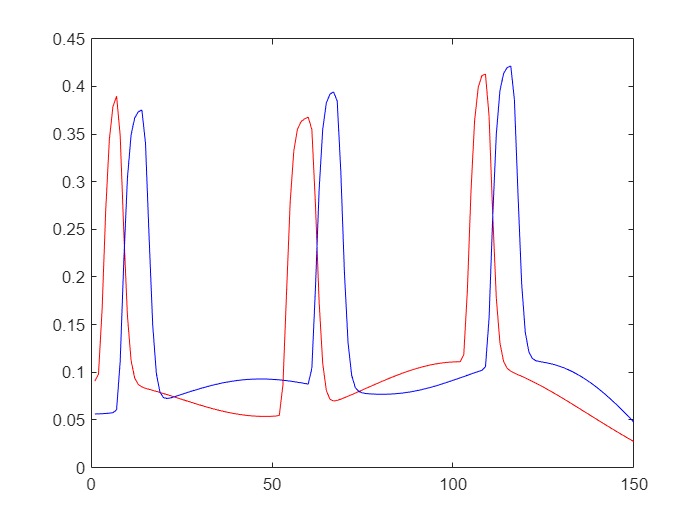

-------------------------------
-------------------------------
    "bingel06"    "-0.16196"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Bingel_et_al_2006\AK\ana1L\SPM.mat
-------------------------------
-------------------------------


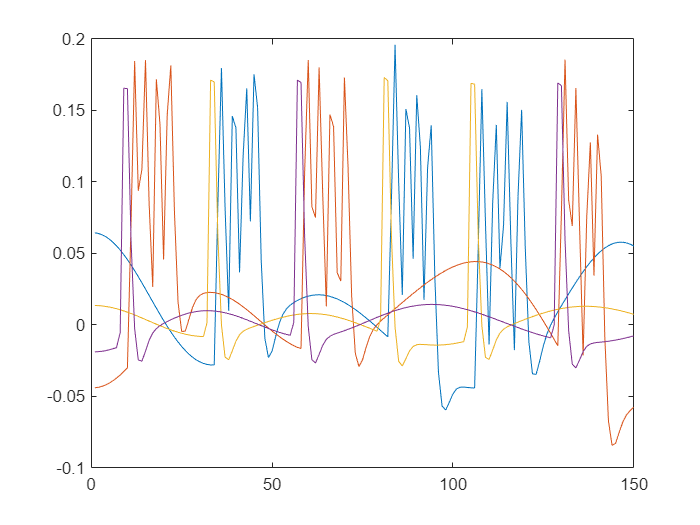

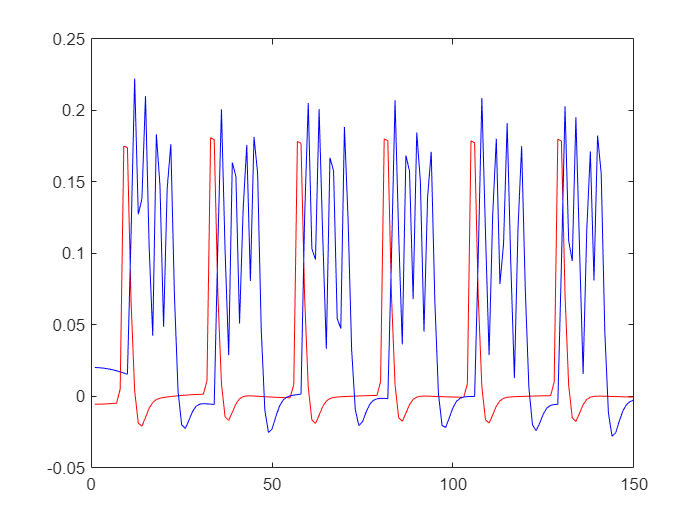

-------------------------------
-------------------------------
    "bingel11"    "-0.22231"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Bingel_et_al_2011\sub02_SPM.mat
-------------------------------
-------------------------------


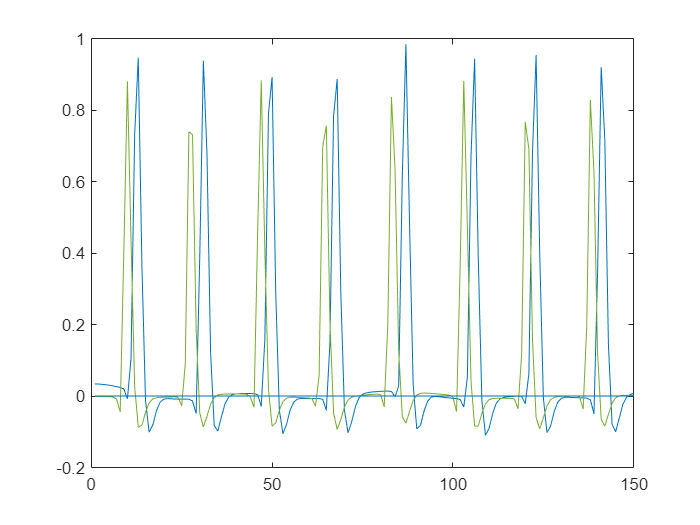

-------------------------------
-------------------------------
    "choi"    "-0.063066"

-------------------------------
-------------------------------


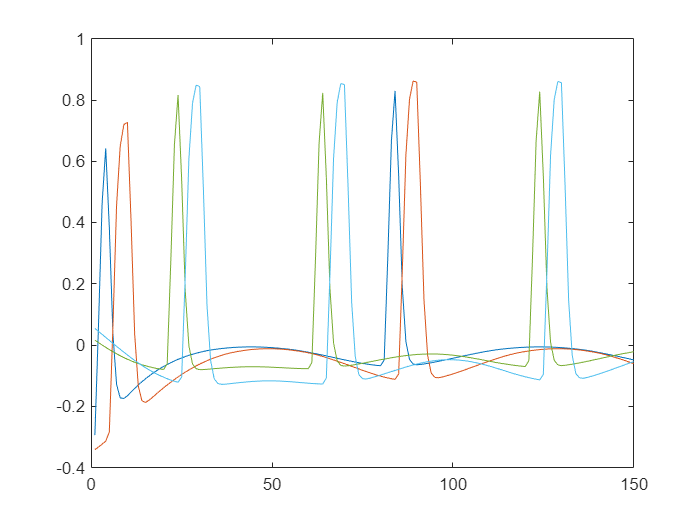

-------------------------------
-------------------------------
    "eippert"    "-0.26144"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Eippert_et_al_2009\01\SPM.mat
-------------------------------
-------------------------------


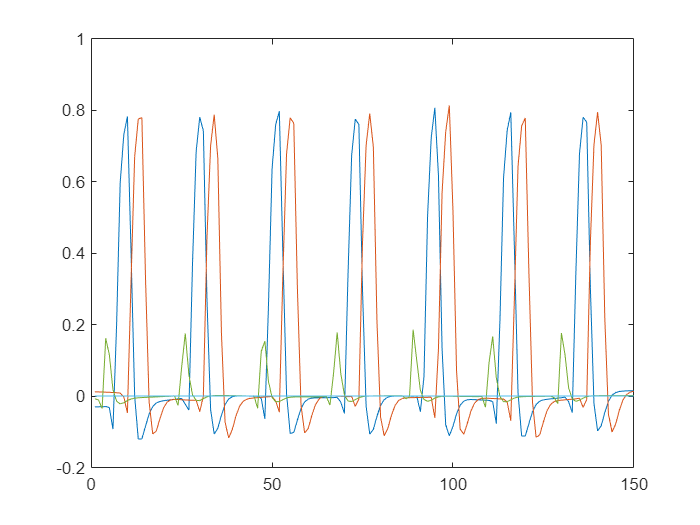

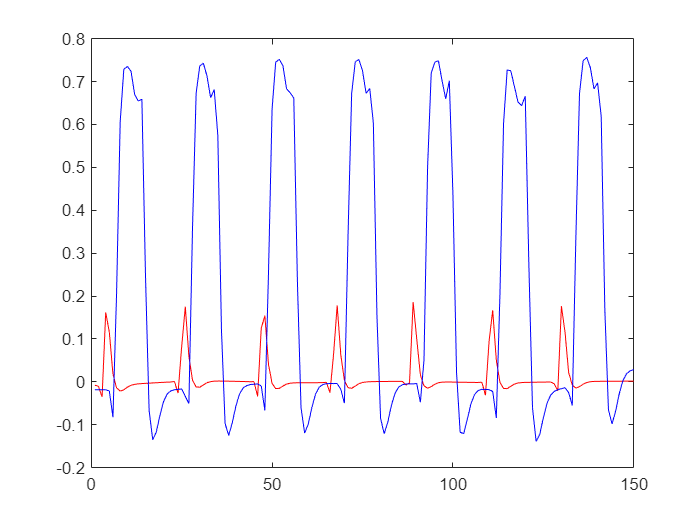

-------------------------------
-------------------------------
    "geuter"    "-0.24604"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Geuter_et_al_2013\sub01\SPM.mat
-------------------------------
-------------------------------


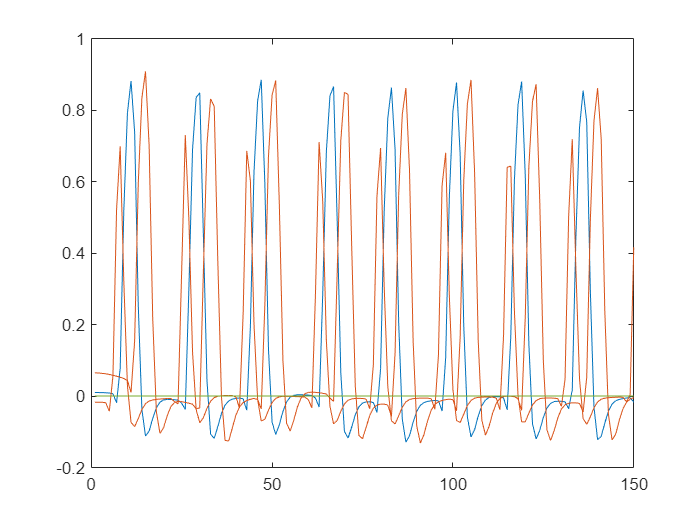

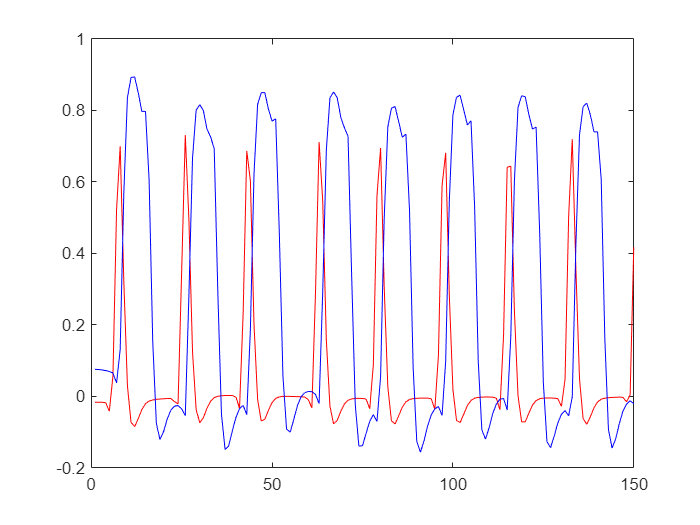

-------------------------------
-------------------------------
    "kessner"    "-0.25942"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Kessner_et_al_201314\sub01_SPM.mat
-------------------------------
-------------------------------


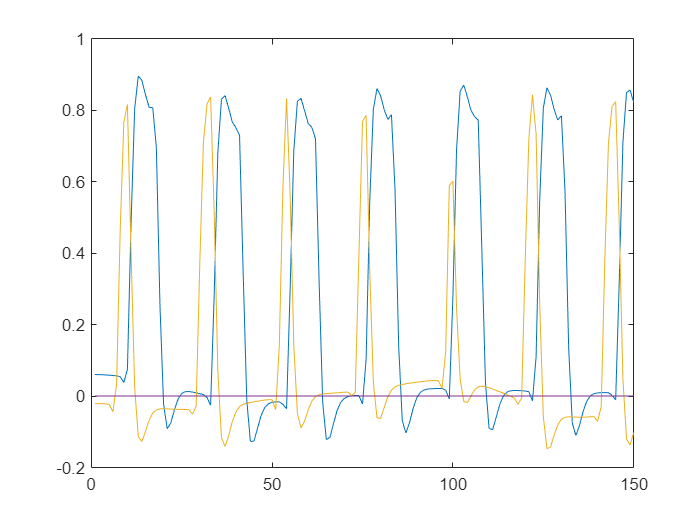

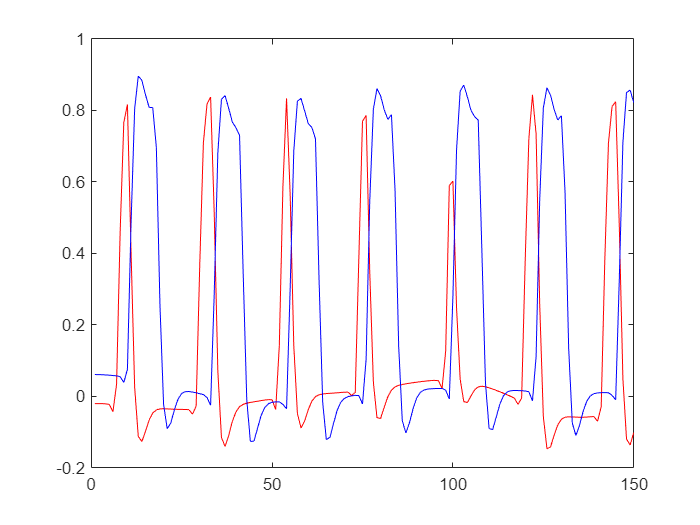

-------------------------------
-------------------------------
    "lui"    "0.31951"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Lui_et_al_2010\TOMO_05\SPM.mat
-------------------------------
-------------------------------


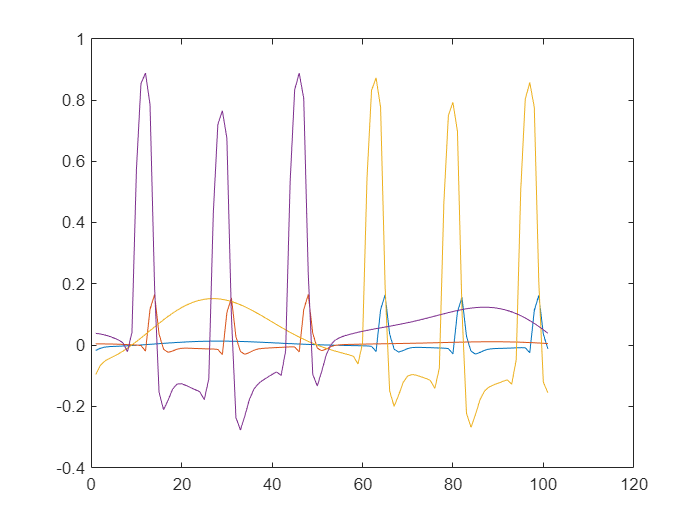

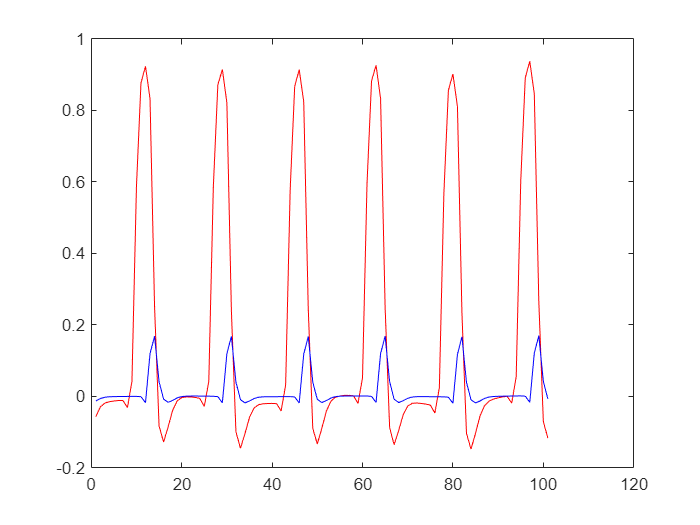

-------------------------------
-------------------------------
    "schenk"    "-0.2847"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Schenk_et_al_2014\sub03\SPM.mat
-------------------------------
-------------------------------


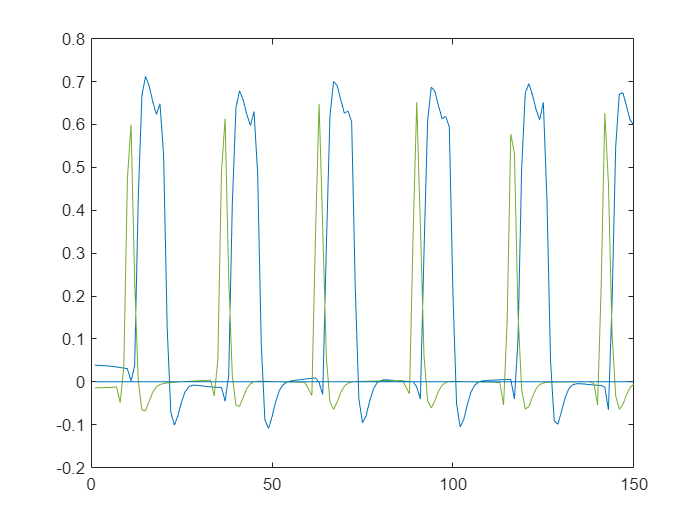

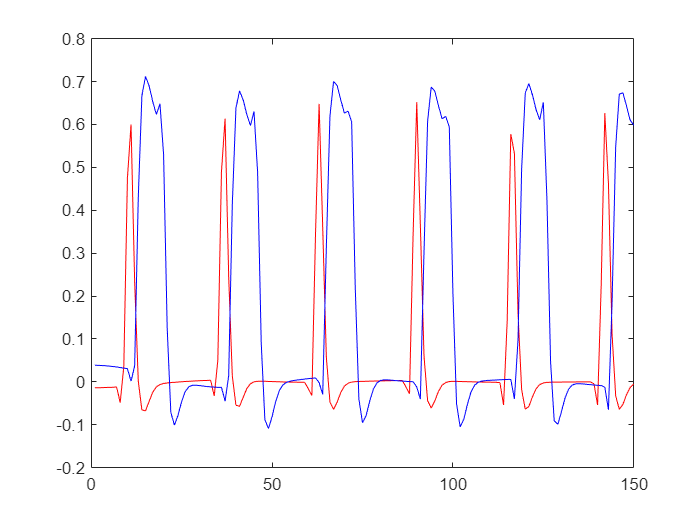

-------------------------------
-------------------------------
    "theysohn"    "-0.11429"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Theysohn_et_al_2014\2101\SPM.mat
-------------------------------
-------------------------------


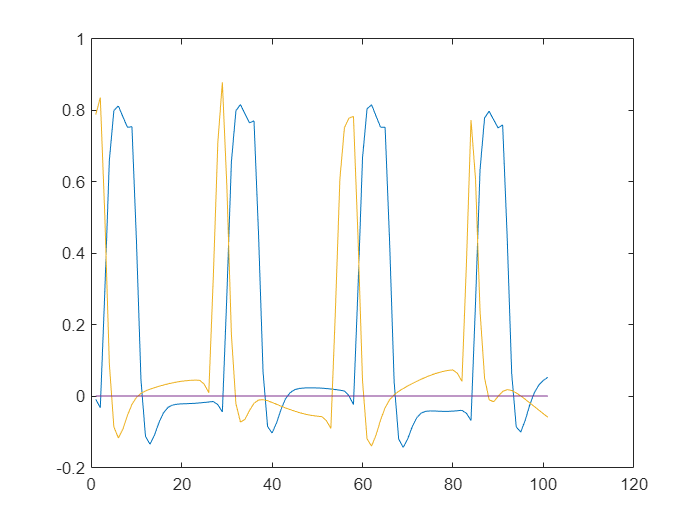

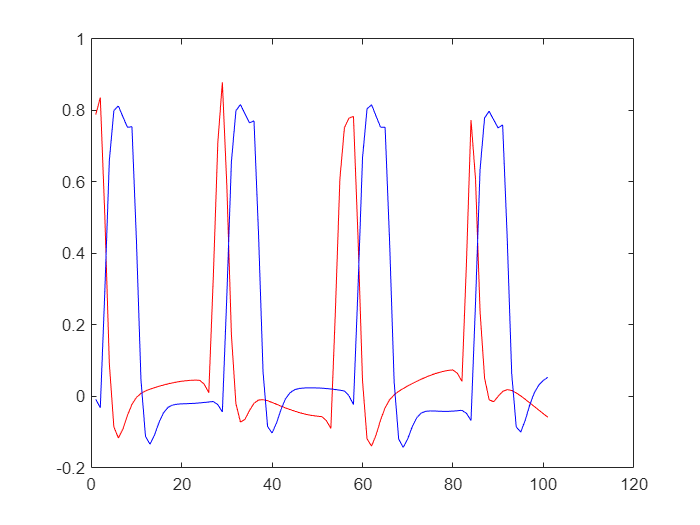

-------------------------------
-------------------------------
    "wager04a_princeton"    "0.38815"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Wager_et_al_2004a_Princeton_shock\AD\SPM_fMRIDesMtx.mat
-------------------------------
-------------------------------


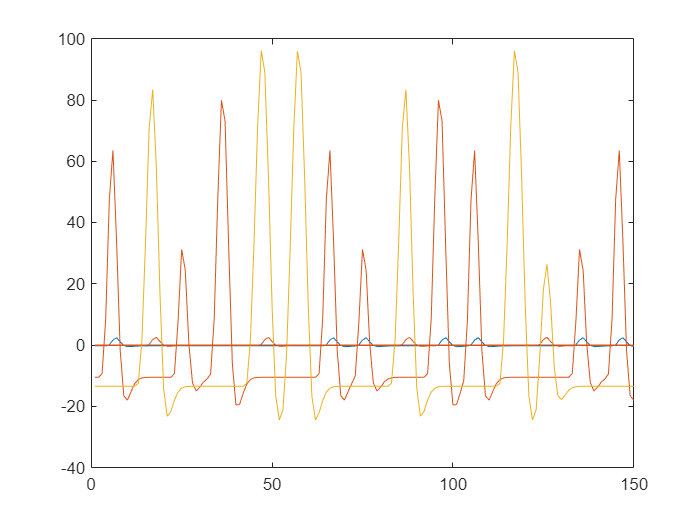

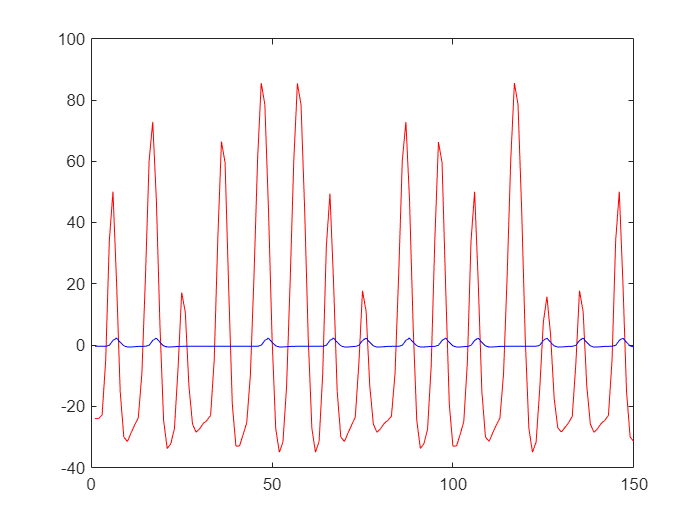

-------------------------------
-------------------------------
    "wager04b_michigan"    "-0.10762"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Wager_et_al_2004b_Michigan_heat\020515mj\SPM_fMRIDesMtx.mat
-------------------------------
-------------------------------


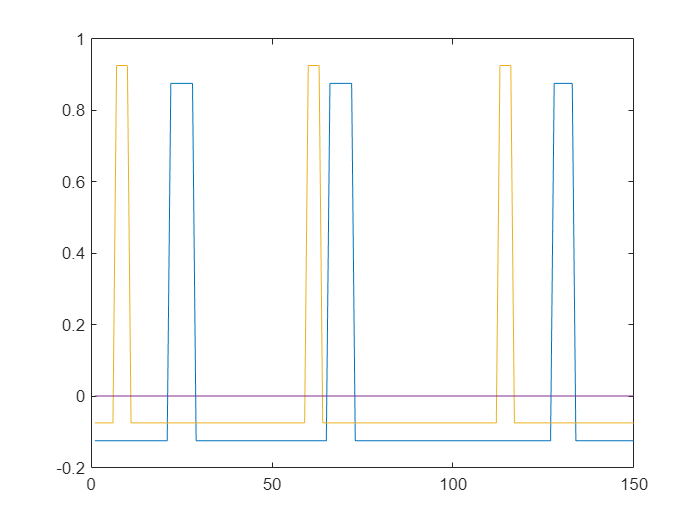

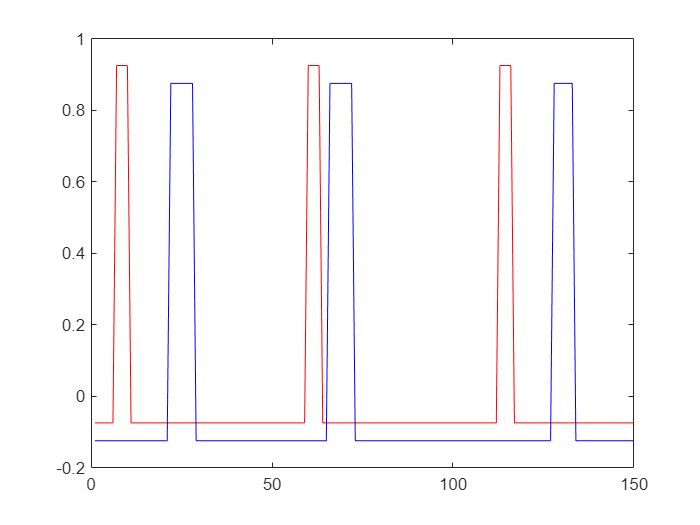

-------------------------------
-------------------------------
    "wrobel"    "-0.28913"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\Datasets\Wrobel_et_al_2014\sub19_SPM.mat
-------------------------------
-------------------------------


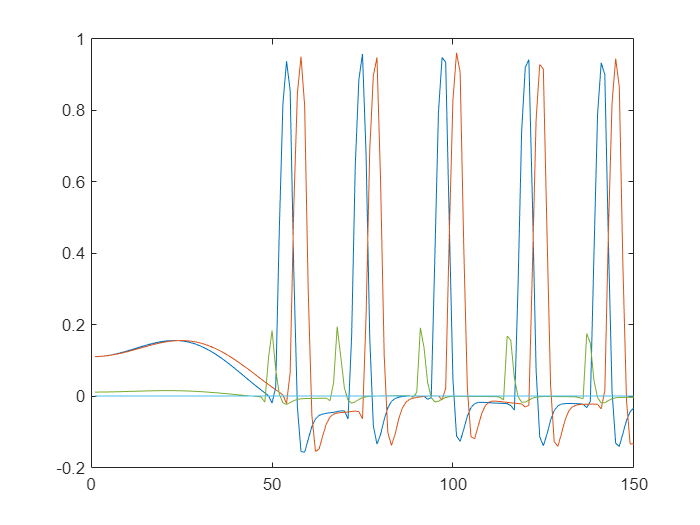

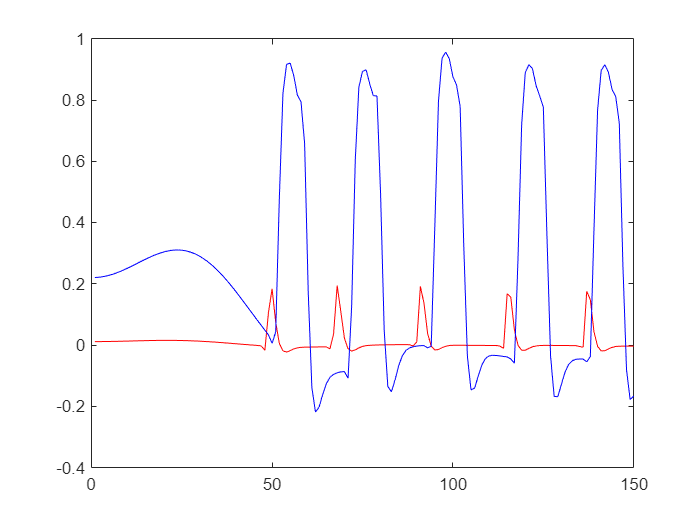

-------------------------------
-------------------------------
    "fehse"    "-0.45669"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\study-Fehse2015\analysis\ersteRechnung\1st\s01\SPM.mat
-------------------------------
-------------------------------


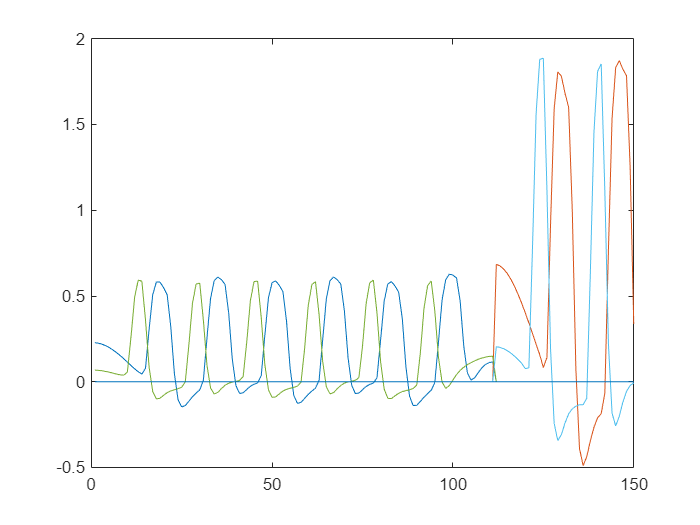

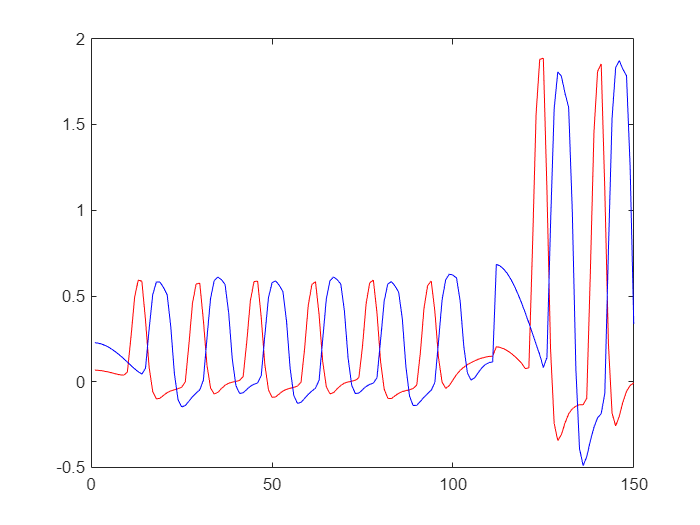

-------------------------------
-------------------------------
    "hartmann"    "0.32438"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\study-Hartmann2020\data\pimb18_01\analysis\analysis_cb_meta\SPM.mat
-------------------------------
-------------------------------


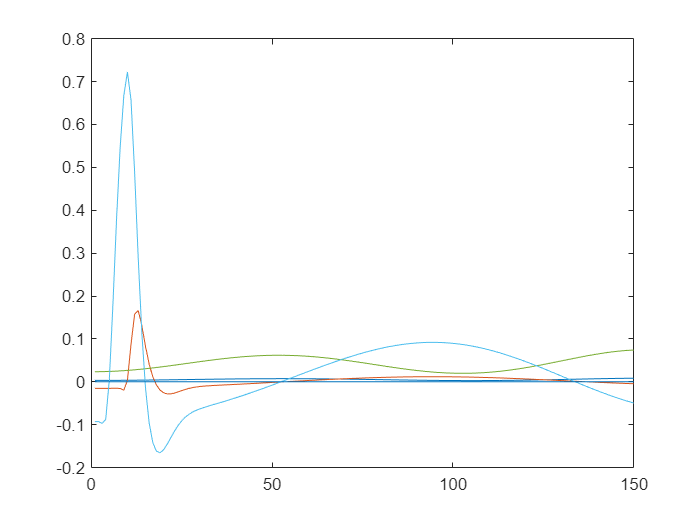

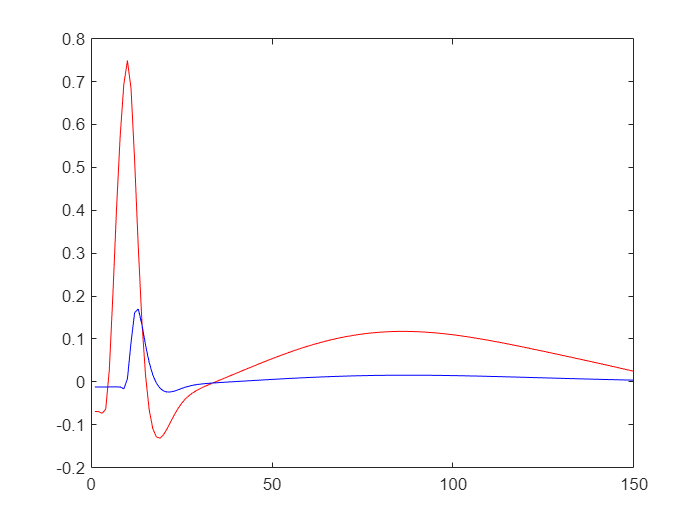

-------------------------------
-------------------------------
    "meulen"    "-0.2417"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\study-Meulen2017\contrast images\suj10\SPM.mat
-------------------------------
-------------------------------


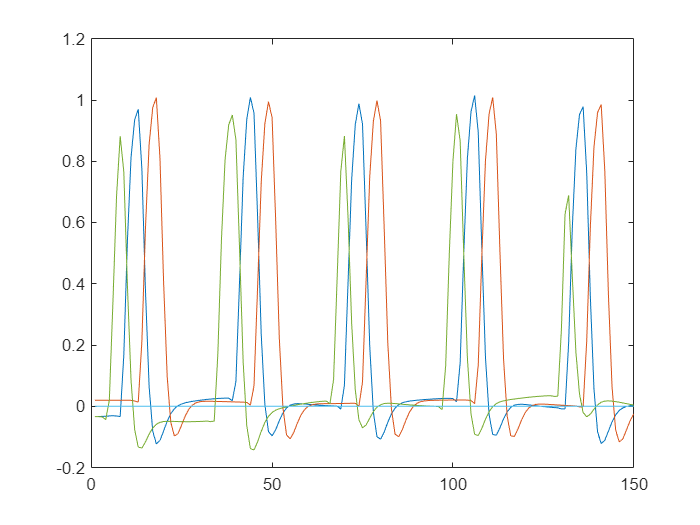

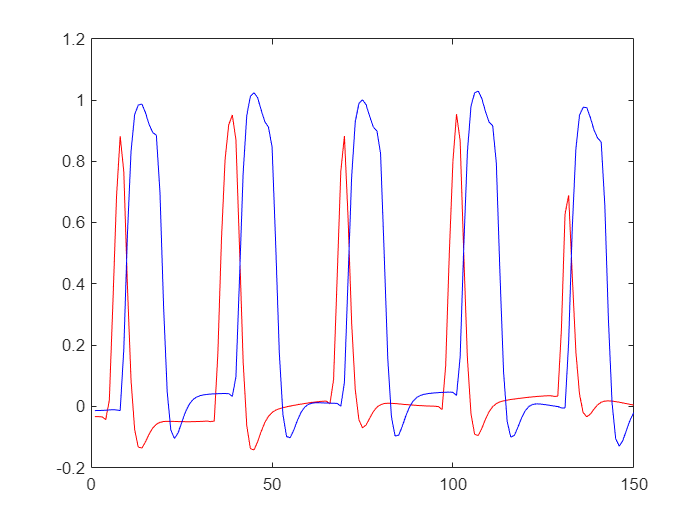

-------------------------------
-------------------------------
    "schenk17"    "-0.047257"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\study-Schenk2017\data3\sub01\functional\SPM.mat
-------------------------------
-------------------------------


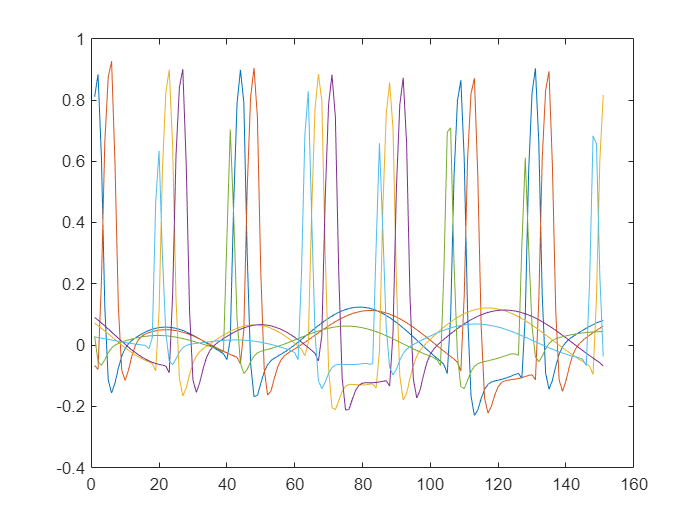

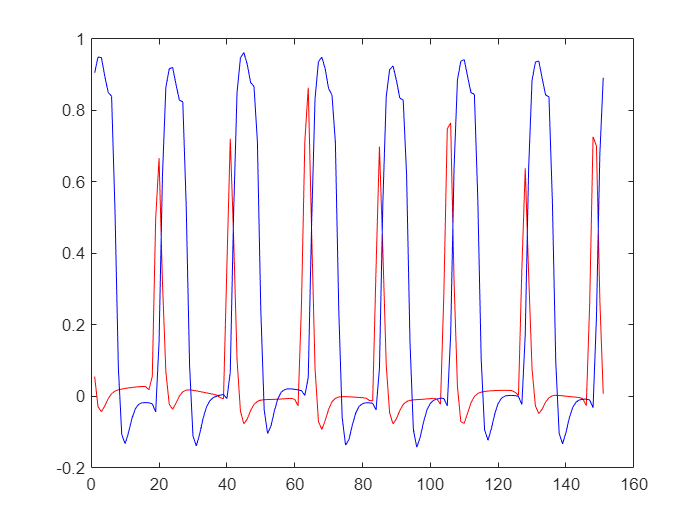

-------------------------------
-------------------------------
    "schenk20"    "-0.011668"

-------------------------------
-------------------------------


-------------------------------
-------------------------------
C:\Users\lenov\Documents\PICO_DATA\study-Schenk2020\data\sub01\functional\SPM.mat
-------------------------------
-------------------------------


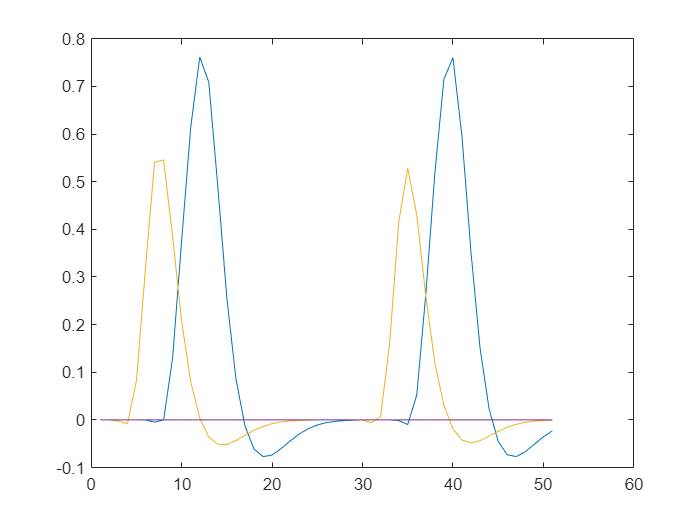

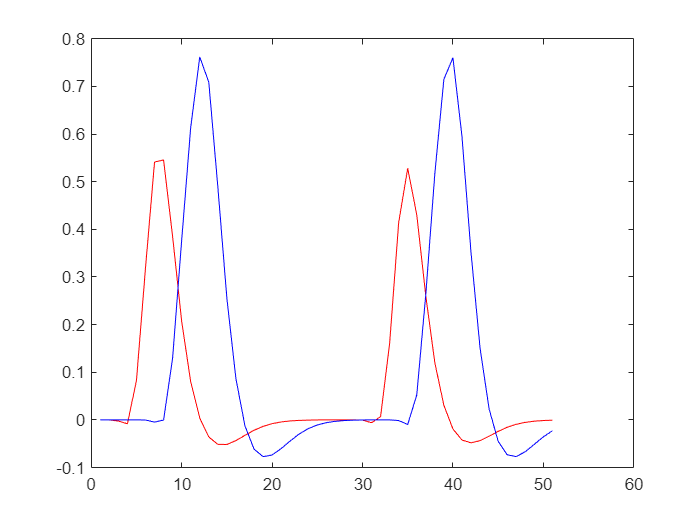


listofstudwithnoindividfolders=["bingel11", "kessner","wrobel"];
listofstudwithdiffinterval=["lui","theysohn","schenk17","schenk20"];
listoftoocopmlicatedmodelledstudies=["choi"];
numofstud=1;%length(anticipationregressoridx);
table(df.study_ID, num2cell((1:26)'), num2cell((1:26)'), ...
    'VariableNames',{'studyID','anticipregressoridx','painregressoridx'});
allanticipstud={};
allcorr=zeros(length(anticipationregressoridx),1);
for studyrank=1:25%1:13%1:height(df)
    if df.anticipismodeled(studyrank) && ~strcmp(df.study_ID{studyrank},listoftoocopmlicatedmodelledstudies)
        if df.dateofdatacollection(studyrank)==2015
            if any(strcmp(df.study_ID{studyrank},listofstudwithnoindividfolders)) 
                fllist=dir(fullfile(fullfile(datapathorig ,df.study_dir{studyrank}), '*SPM.mat'));
            elseif any(strcmp(df.study_ID{studyrank},["wager04a_princeton","wager04b_michigan"]))
                fllist=dir(fullfile(fullfile(datapathorig ,df.study_dir{studyrank}), '**','SPM_fMRIDesMtx.mat'));
            else
                fllist=dir(fullfile(fullfile(datapathorig ,df.study_dir{studyrank}), '**', 'SPM.mat'));
            end
        elseif df.dateofdatacollection(studyrank)==2021
            if any(strcmp(df.study_ID{studyrank},["fehse"]))
                fllist=dir(fullfile(fullfile(datpathnew ,df.study_dir{studyrank},'analysis\ersteRechnung\1st\s*'), '**', 'SPM.mat'));
            elseif any(strcmp(df.study_ID{studyrank},["schenk17"]))
                fllist=dir(fullfile(fullfile(datpathnew ,df.study_dir{studyrank}), '**', '\functional\SPM.mat'));
            else
                fllist=dir(fullfile(fullfile(datpathnew ,df.study_dir{studyrank}), '**', 'SPM.mat'));
            end
        end
        load(fullfile(fllist(1).folder,fllist(1).name))
        if any(strcmp(df.study_ID{studyrank},listofstudwithdiffinterval))
            if strcmp(df.study_ID{studyrank},"lui")
                imgdintrval=500:600;
            elseif strcmp(df.study_ID{studyrank},"theysohn")
                imgdintrval=300:400;
            elseif strcmp(df.study_ID{studyrank},"schenk17")
                imgdintrval=400:550;
            elseif strcmp(df.study_ID{studyrank},"schenk20")
                imgdintrval=650:700;
            end

        else
            imgdintrval=1:150;
        end
        %todo one has to specify the study level anticipation and pain
        %model conditions in the SPM.xX.X design matrix.
        interestingids=[painregressionidx{numofstud} anticipationregressoridx{numofstud}];
        if any(strcmp(df.study_ID{studyrank},["wager04a_princeton", "wager04b_michigan"]))
            anticipreg=sum(xX.X(:,anticipationregressoridx{numofstud}),2);
            painreg=sum(xX.X(:,painregressionidx{numofstud}),2);
            dtmtrx=xX.X;
%             anticipreg=sum(xX.xKXs.X(:,anticipationregressoridx{numofstud}),2);
%             painreg=sum(xX.xKXs.X(:,painregressionidx{numofstud}),2);
%             dtmtrx=xX.xKXs.X;
        else
            anticipreg=sum(SPM.xX.X(:,anticipationregressoridx{numofstud}),2);
            painreg=sum(SPM.xX.X(:,painregressionidx{numofstud}),2);
            dtmtrx=SPM.xX.X;
%             anticipreg=sum(SPM.xX.xKXs.X(:,anticipationregressoridx{numofstud}),2);
%             painreg=sum(SPM.xX.xKXs.X(:,painregressionidx{numofstud}),2);
%             dtmtrx=SPM.xX.xKXs.X;
            
        end
        antpaincorr=corrcoef([anticipreg painreg]);
        textwrt([df.study_ID{studyrank},string(antpaincorr(1,2))])
        textwrt(fullfile(fllist(1).folder,fllist(1).name))
        figure()
        plot(dtmtrx(imgdintrval,interestingids))
        hold off
        figure()
        plot(anticipreg(imgdintrval),"Color","red")
        hold on
        plot(painreg(imgdintrval),"Color","blue")
        hold off
%         plot(1:length(anticipreg),anticipreg,1:length(painreg),painreg)
%         figure()
%         h=heatmap(vertcat({'anticip' ,'pain'}), ...
%             vertcat({'anticip' ,'pain'}), ... %SPM.Vbeta(interestingids).descrip
%             antpaincorr);
%         h.Title = df.study_ID(studyrank);
        allanticipstud{numofstud}=df.study_ID{studyrank};
        allcorr(numofstud)=antpaincorr(1,2);
        numofstud=numofstud+1;
    elseif strcmp(listoftoocopmlicatedmodelledstudies,df.study_ID{studyrank})

        
        maki=[ datapathorig  '\Choi_et_al_2011\DesignMatrix_Subj_D_Exp_1_1potent.txt' ];
        maki100=[ datapathorig  '\Choi_et_al_2011\DesignMatrix_Subj_D_Exp_1_100potent.txt'];
        makicontr=[ datapathorig  '\Choi_et_al_2011\DesignMatrix_Subj_D_Exp_1_control.txt'];
        muki=dlmread(maki,'\t',[5, 0, 304,13]);
        muki100=dlmread(maki100,'\t',[5, 0, 304,13]);
        mukicontr=dlmread(makicontr,'\t',[5, 0, 304,13]);
        antpaincorrchoi=corrcoef([muki(:,1); muki100(:,1);mukicontr(:,1)],[muki(:,3); muki100(:,3);mukicontr(:,3)]);
        textwrt([df.study_ID{studyrank},string(antpaincorrchoi(1,2))])

        plot(muki(1:150,[1 3]),'DisplayName','muki(:,1:4)')
        hold on
        plot(muki100(1:150,[1 3]),'DisplayName','muki100(:,1:4)')
        hold on 
        plot(muki100(1:150,[1 3]),'DisplayName','muki100(:,1:4)')
        hold off
%         allanticipstud{numofstud}=df.study_ID{studyrank};
%         allcorr(numofstud)=antpaincorr(1,2);
%         numofstud=numofstud+1;
    end
    


end

asd

allanticipstud{end+1}=df.study_ID{4};
allcorr(end+1)=antpaincorrchoi(1,2);

table(allcorr,allanticipstud')

function textwrt(txt)

The end operator must be used within an array index expression.

    disp('-------------------------------')
    disp('-------------------------------')
    disp(txt)
    disp('-------------------------------')
    disp('-------------------------------')
end